% 输入
clc;
A = [3,4,5;2,3,4;1,2,7]

A =      3     4     5
     2     3     4
     1     2     7


% 分行输入
clc;
A = [3,4,5
    2,3,4
    1,2,8]

A =      3     4     5
     2     3     4
     1     2     8


% 引用
A(2,2) = 99

A =      3     4     5
     2    99     4
     1     2     8


% :的使用
B = 8:11

B =      8     9    10    11


% 矩阵的加减法
clear;
A = [1,2,3];

A =      1     2     3


B = [2,3,4]

B =      2     3     4


A+B

ans =      3     5     7


B-A

ans =      1     1     1


% 矩阵的乘法
A=[1 2 3; 4 5 6]

A =      1     2     3
     4     5     6


B=[3;2;3]

B =      3
     2
     3


A*B

ans =     16
    40


% 矩阵的除法
A = [1 -1 -1
    10 10 0
    10 -10 10]

A =      1    -1    -1
    10    10     0
    10   -10    10


b = [0
    10
    0]

b =      0
    10
     0


b\A

ans =      1     1     0


% 矩阵的转置
A

A =      1    -1    -1
    10    10     0
    10   -10    10


A'

ans =      1    10    10
    -1    10   -10
    -1     0    10


% 矩阵的逆
A = [1 1.5 2 9 7
    0 3.6 0.5 -4 4
    7 10 -3 22 33
    3 7 8.5 21 6
    3 8 0 90 -20]

A =     1.0000    1.5000    2.0000    9.0000    7.0000
         0    3.6000    0.5000   -4.0000    4.0000
    7.0000   10.0000   -3.0000   22.0000   33.0000
    3.0000    7.0000    8.5000   21.0000    6.0000
    3.0000    8.0000         0   90.0000  -20.0000


inv(A)

ans =    -0.8152   -0.5434    0.1594    0.2800   -0.0469
   -0.1127    0.2510    0.0026    0.0127    0.0188
    0.0813   -0.0459   -0.0401    0.0871   -0.0207
    0.0739    0.0031   -0.0064   -0.0198    0.0100
    0.1652    0.0329   -0.0037   -0.0421   -0.0043


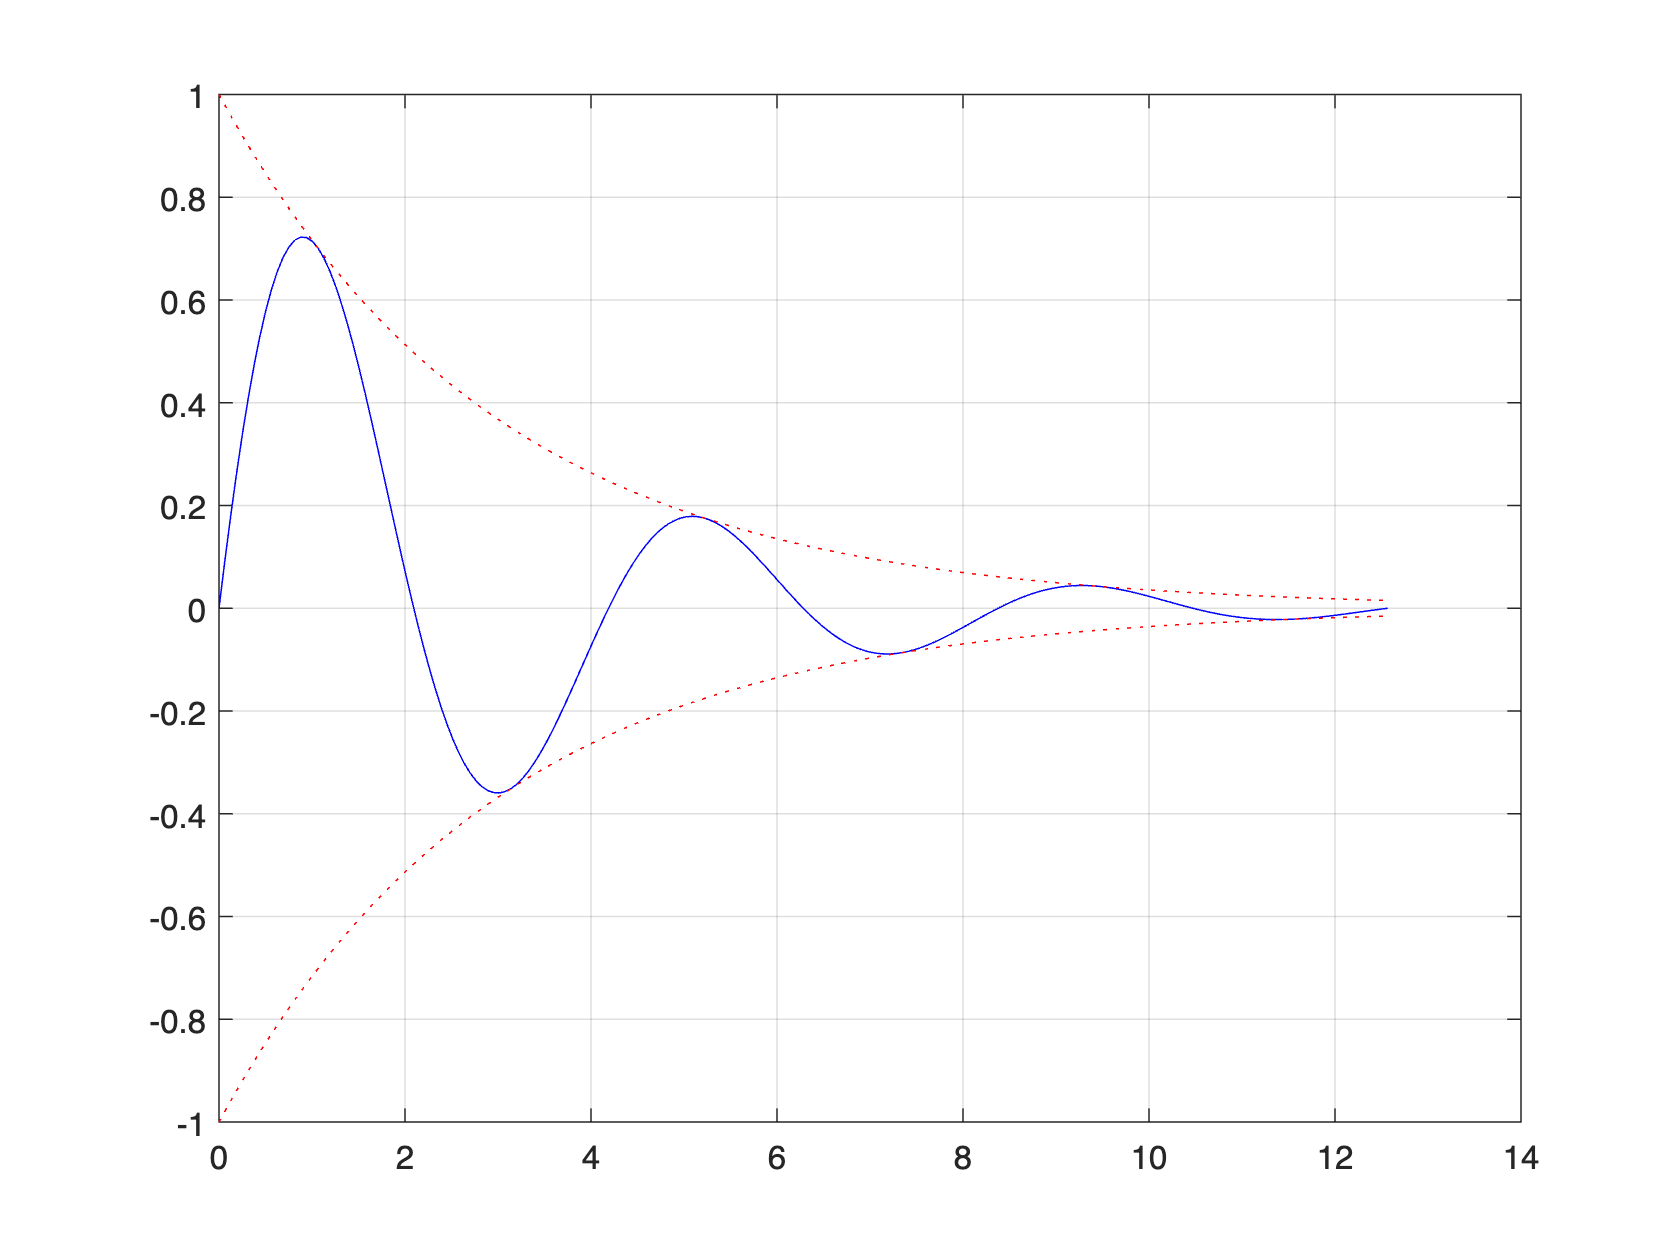

t=0:pi/50:4*pi;
y0=exp(-t/3);	
y=exp(-t/3).*sin(1.5*t);
plot(t,y,'-b',t,y0,':r',t,-y0,':r')
grid 

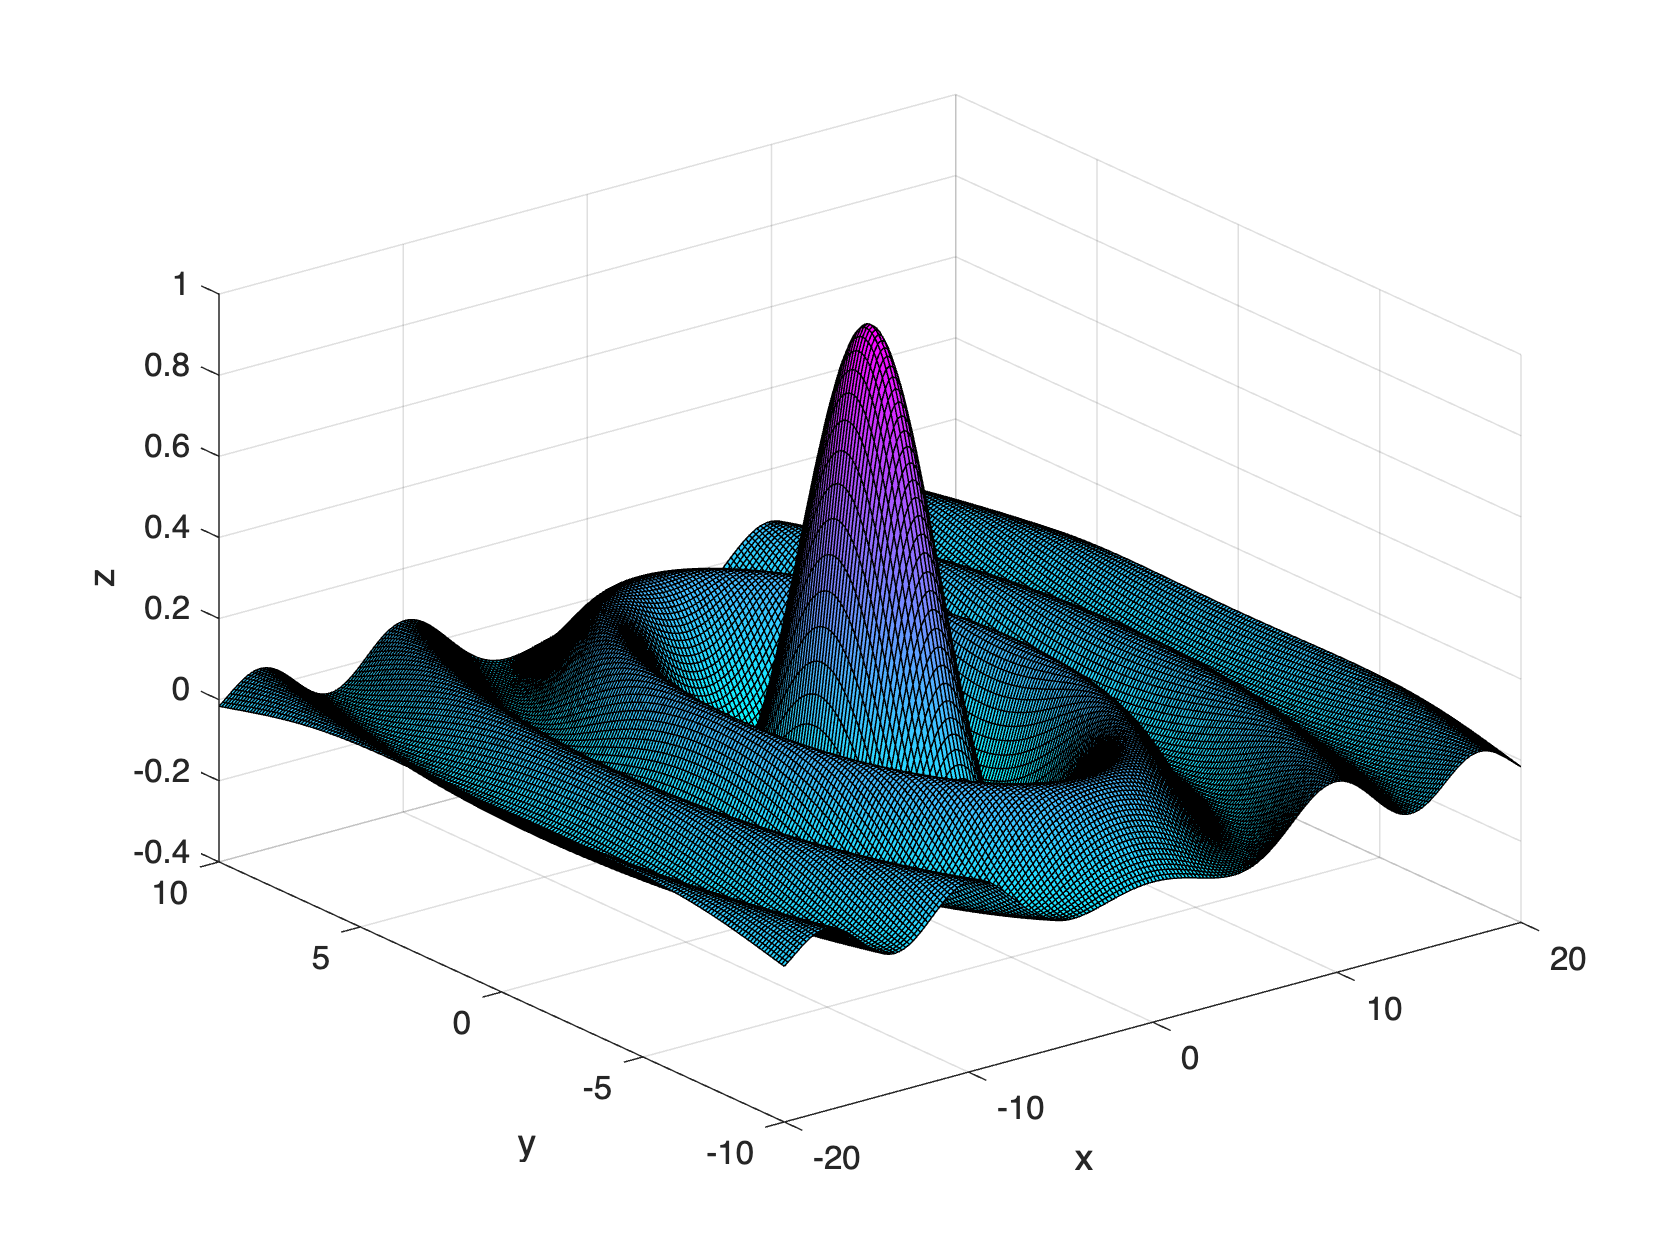

clear;
x=-10:0.1:10;
y=x';
X=ones(size(y))*x*2;
Y=y*ones(size(x));
R=sqrt(X.^2+Y.^2)+eps;	%<5>
Z=sin(R)./R;				%<6>
surf(X,Y,Z);				%
colormap(cool) 			%
xlabel('x'),ylabel('y'),zlabel('z') 

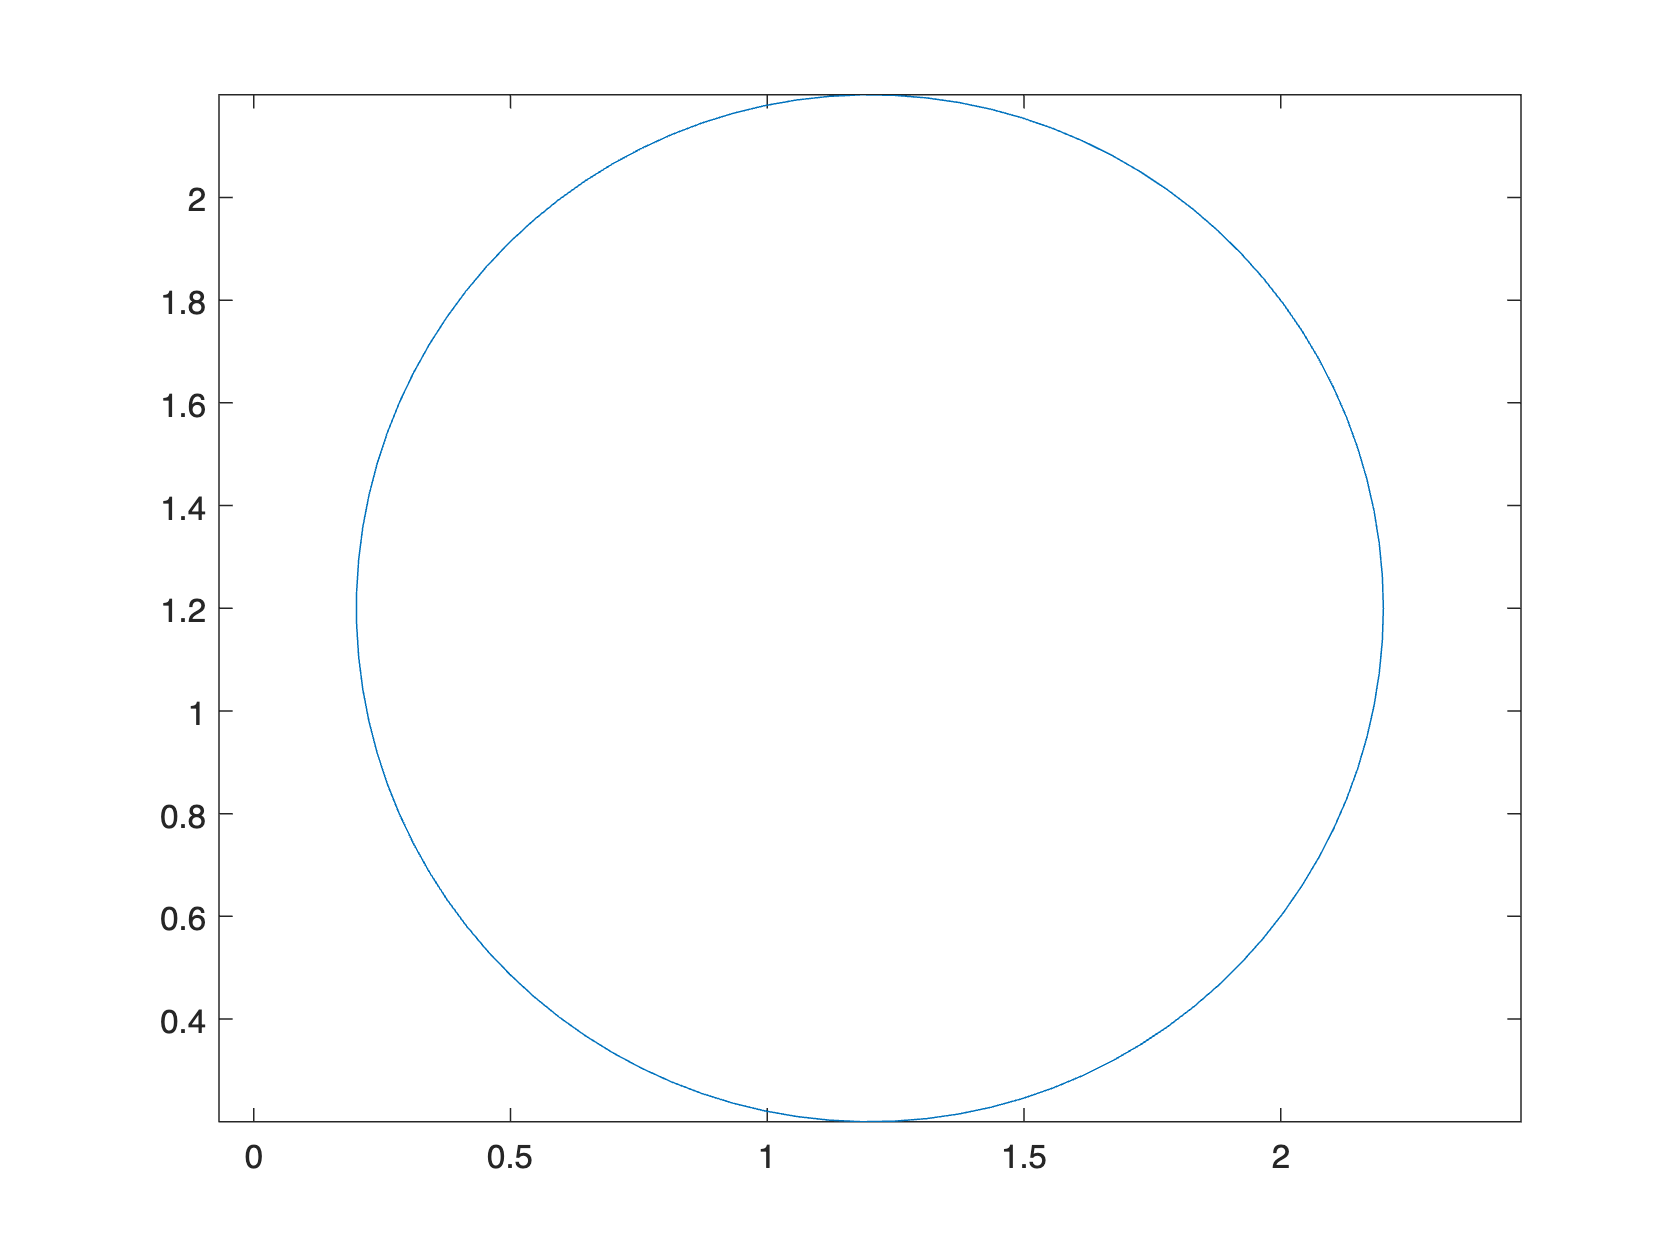

r = 1;
xc = 1.2;
yc = 1.2;
theta = linspace(0,2*pi);
x = r*cos(theta) + xc;
y = r*sin(theta) + yc;
plot(x,y)
axis equal

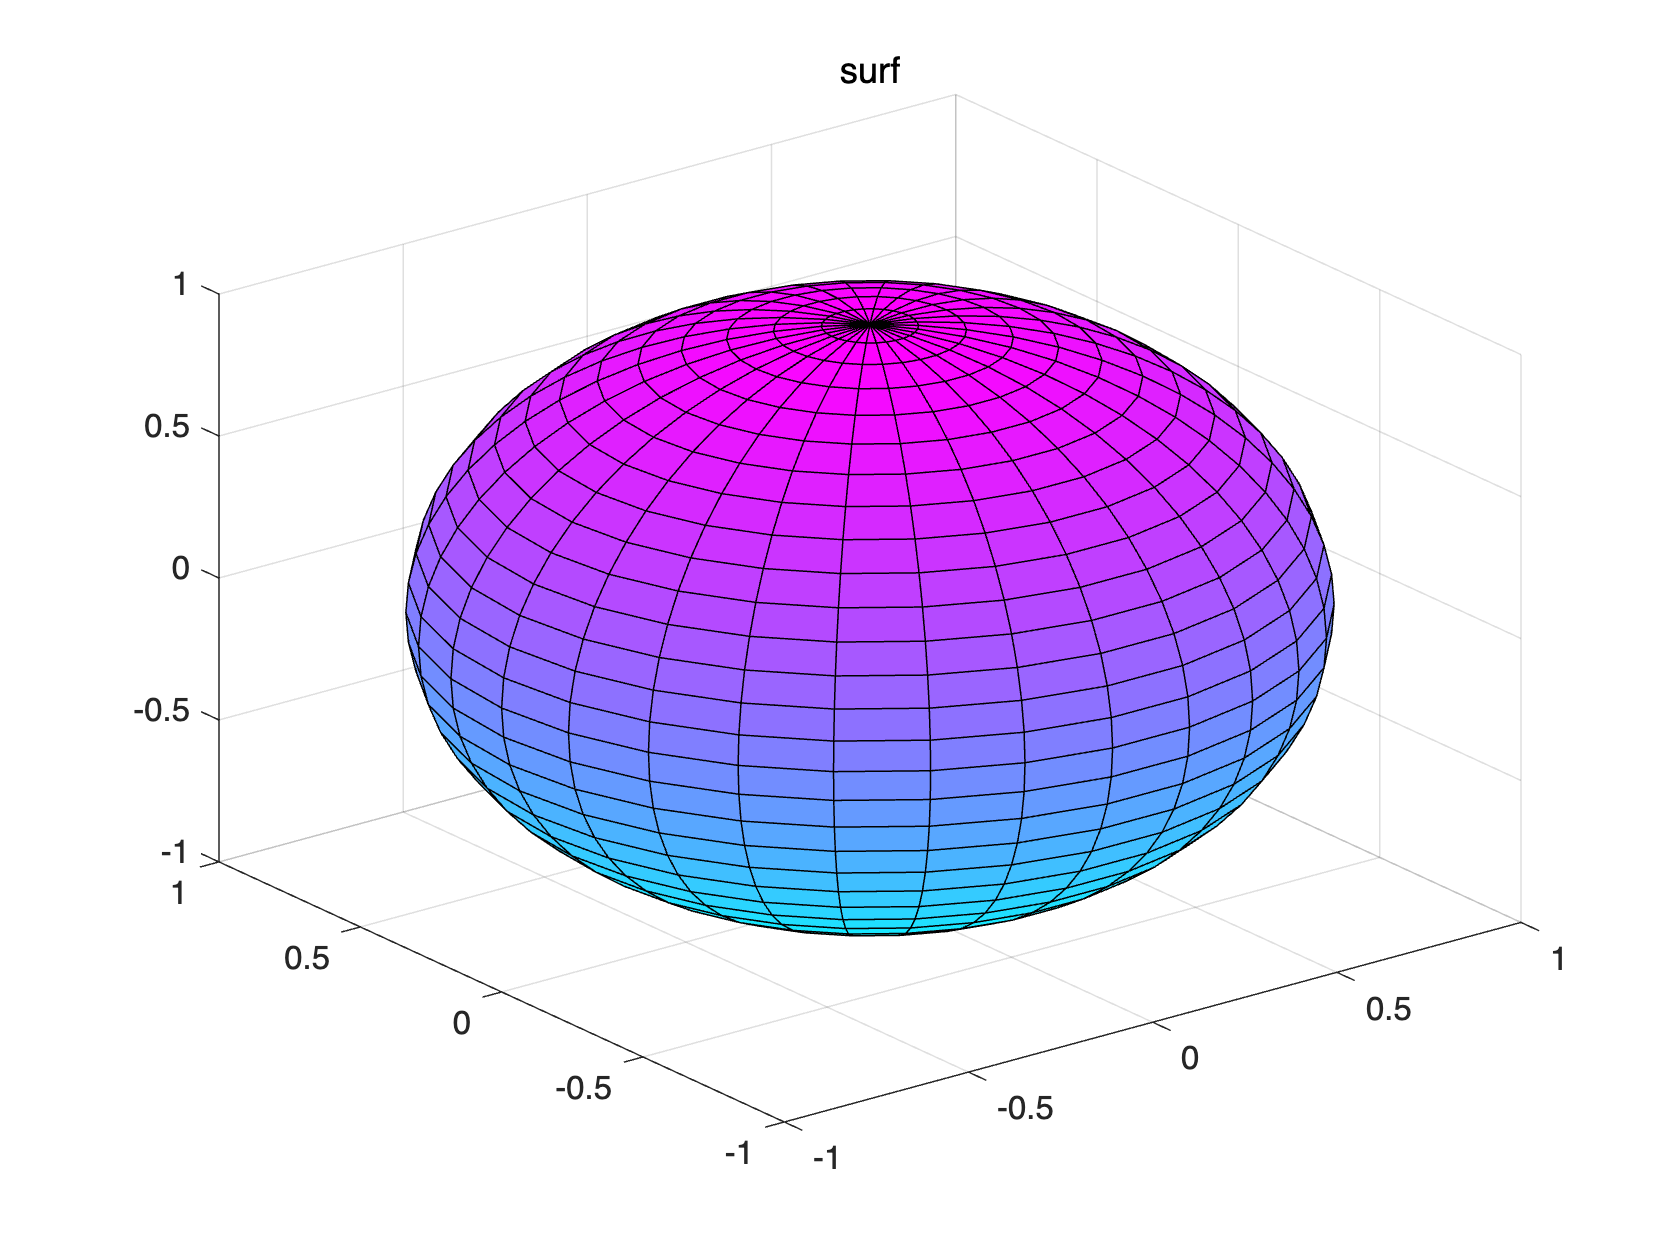

[u,v,w] = sphere(30);
surf(u,v,w)
title('surf')